% Parameters
r = 0.56; % Growth rate (cells/day)
K = 5e8; % Carrying capacity (cells)
P0 = 3000 * 120; % Initial population (cells)
total_days = 25; % Total simulation time (days)

dt_values = [1/24, 1/1440, 1/86400]; % Time intervals (days)
colors = ['r', 'g', 'b']; % Colors for different dt plots

% Preallocation for population at 3 days
pop_at_3_days = zeros(length(dt_values), 1);

figure;

for i = 1:length(dt_values)
    dt = dt_values(i); % Time step
    num_steps = ceil(total_days / dt); % Number of steps
    
    t = (0:num_steps) * dt; % Time vector
    P = zeros(size(t)); % Population vector
    P(1) = P0; % Initial condition
    
    % Euler's method
    for n = 1:num_steps
        dPdt = r * P(n) * (1 - P(n) / K);
        P(n + 1) = P(n) + dPdt * dt;
    end
    
    % Save population at 3 days
    idx_3_days = find(t >= 3, 1);
    pop_at_3_days(i) = P(idx_3_days);
    
    % Plot P(t)
    subplot(3, 1, 1);
    plot(t, P, colors(i)); hold on;
    title('Population Growth P(t)');
    xlabel('Time (days)'); ylabel('Population');
    
    % Plot dP(t)/dt
    subplot(3, 1, 2);
    dPdt = r * P .* (1 - P / K);
    plot(t, dPdt, colors(i)); hold on;
    title('Growth Rate dP(t)/dt');
    xlabel('Time (days)'); ylabel('Growth Rate');
end

legend(cellstr(num2str(dt_values', '\Delta t = %.0e')));

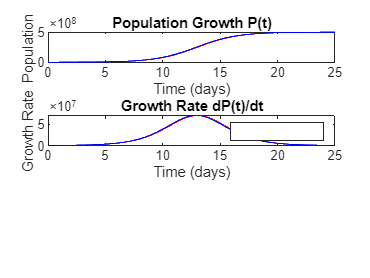

hold off;


% Calculate percentage error
smallest_dt_pop = pop_at_3_days(end);
errors = abs((pop_at_3_days(1:end-1) - smallest_dt_pop) / smallest_dt_pop) * 100;

% Display results
disp('Population at 3 days for each \Dt:\n');

Population at 3 days for each \Dt:\n


for i = 1:length(dt_values)
    fprintf('dt = %.0e: P(3) = %.2f cells\n', dt_values(i), pop_at_3_days(i));
end

dt = 4e-02: P(3) = 1889010.93 cells
dt = 7e-04: P(3) = 1924923.78 cells
dt = 1e-05: P(3) = 1925537.36 cells



fprintf('\nPercentage errors compared to smallest \Dt:\n');


Percentage errors compared to smallest 

for i = 1:length(errors)
    fprintf('dt = %.0e: Error = %.2f%%\n', dt_values(i), errors(i));
end

dt = 4e-02: Error = 1.90%
dt = 7e-04: Error = 0.03%
